# 3 基礎解説：数列のマジック（単振動・減衰振動の数値実験）

## 3.1 ｢数列のマジック｣の種明かし: MATLAB Live Script (Python併記あり)の概要

### 大学入学したての学生のみなさんへの説明

本 MATLAB プログラムコード（Live Script形式）は，立命館大学理工学部物理科学科の1年生の導入科目「ミクロとマクロの世界」[1, 2, 3]において，入学した最初の月の最初の授業に実践されてきた｢数列のマジック｣の教材をベースにしています．ミクロな局所ルール（$u_n =a\times u_{n-1} -b\times u_{n-2}$; 3項の数列漸化式）の係数をわずかに変化させるだけで，マクロには異なる関数の曲線に見えます．これを体感させて，高校の「数学」「物理」「情報Ｉ」から，大学の「数学」「物理学」「計算機と情報の科学と工学」への円滑な接続を目指していました．

従来の計算機の導入教育で頻繁に用いられる前進差分法的手法（オイラー法）[4]の詳細な数学的解説を経ずに学べるように設計しました．

### *大学専門課程学生のみなさんへの説明*

*この｢数列のマジック｣が，大学専門課程の多くの科目と関連し，それらの導入にも使えるということは，「ミクロとマクロの世界」を担当していた時から意識していました．今回の教育公開コンテンツを組み立てるにあたり，生成AIに頼んだら，README.md[5]の相関図や，専門課程で習うことを使った説明 [6]や，｢数列のマジック｣的数値配列の演算が実際にどう使われているか[7]などのコンテンツが用意できました．*

*４次のルンゲ・クッタ法[4]との比較も，元々の１年生用教材には含まれていませんでした．筆者が今回含めようと思ったのは，2026年7月に筆者が生成AIにそうすると面白いと教えてもらったからです．４次のルンゲ・クッタ法は，計算機導入教育で頻繁に用いられるオイラー法（1次のルンゲ・クッタ法）の高精度版で，色々な分野で常微分方程式の高精度ツールの決定版と扱われています．しかし，１年生の入学したての月に教えることは不可能だったので，１年生用の教材には含めませんでした．ところが，｢数列のマジック｣が，ルンゲ・クッタ法が直面した困難[8]を回避できる性質を持っていて，本Live Scriptの3.7の図がそれを示していると生成AIが教えてくれました．｢数列のマジック｣の計算機コードは非常に単純なので，大学専門課程学生のみなさんが，分子動力学や天文学，AI（ディープラーニング）において，前進差分的・エネルギー非保存的方法が経験した困難[8]や，それらがどう回避されたかを勉強するときに，うまく活用してください．これらの専門分野は筆者と異なるので，これほどまでに，最新の研究分野まで全体を俯瞰する機会がありませんでした．生成AIの俯瞰能力の高さを楽しむことができました．*

### MATLAB Live Scriptを楽しむのに必要な環境

このMATLAB Live Scriptを楽しむためには，MATLAB 2022aもしくはそれより新しいバージョンが必要です[9]．また，MATLABのLive Editor環境が必要です[9]．この環境は高度な機能を備える反面，スマートフォンやタブレットのモバイルブラウザ上での実行には対応していません．そのため本資料では，学生が手元のモバイル端末からでも手軽にシミュレーションを実行・観察できるよう，ブラウザでインタラクティブに動くHTMLアプリ[10]や，モバイルブラウザからでも実行可能なGoogle Colab（Python）を用いたアプローチについても併記・提供しています．

2026年7月現在，チャット型生成AIが広く普及し，とても便利になっています．以下の｢3.2節の内容｣を与えただけで，上記HTMLアプリを生成してくれました．MATLABコードからPythonコードへの翻訳も一瞬でした．

## 3.2 ｢数列のマジック｣の基本５形のMATLABとPythonのコード

### 3.2.1  $$(a,b)=(2,1)$ $の場合

以下の1行は，パラメータ $$(a,b)=(2,1)$ $の場合のMATLABコードです．実行すると，画面には右肩上がりの直線（加速度0の運動）が描き出されます ．ただし，u(1)=0，u(2)=1です．

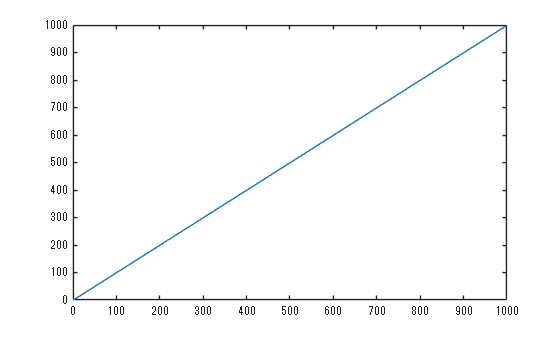

clear; a=2; b=1; u(1)=0; u(2)=1; for n=3:1000; u(n)=u(n-1)*a - u(n-2)*b; end; plot(u)

以下のPythonコードは，上のMATLABコードに対応するものです．

MATLABのu(1)=0 は，Pythonの u[0]=0に対応します．また，MATLABの"for n=3:1000; ...; end"は，Pythonの "for n in range(2, n_max):"に対応します．両者の添え字番号がずれていることに注意して下さい．また，上のPythonコードにおける字下げ（インデント）されている行は，nが3から999まで繰り返されるという意味です．コピペするときに，字下げが崩れていないように注意して下さい．

### 3.2.2  $$(a,b)$ $が別の値の場合

係数を $(a,b) = (1.9999, 1)$, $(1.99, 1)$, $(1.99, 0.99)$, $(1.98, 0.99)$ など，わずかに書き換えて実行してください．正弦波（長周期・短周期単振動），指数関数的に一定値に漸近する曲線，あるいは減衰振動など，大学で習う，物理の力学系や電子回路応答に対応する多様な数値近似解に一変します．上記以外の組み合わせにすると，ある特定の値を境に，異なる特徴の曲線になることに気付きます．上で紹介したインタラクティブに動くHTMLアプリ[10]ならもっと容易に観察できるでしょう．

### 3.2.3 初期値が1の場合

初期値を0から1に書き換えて実行すると，正弦関数は余弦関数に一変します．

## 3.3 ｢数列のマジック｣の正体：微分方程式の有限差分解法

シンプルな数列漸化式から正弦波が描かれる理由は，大学で習う，物理学における運動方程式（微分方程式）の数値近似解（Numerical Approximate Solution）を計算することに他ならないからです．

質量 $m=1\text{ kg}$ のおもりに，バネ定数 $k=1\text{ N/m}$ のバネが繋がれた調和振動子系を考えます ．おもりの位置を $u$ とすると，運動方程式（微分方程式）は $\frac{d^2u}{dt^2} + u = 0$ となります ．数学的に得られる理論厳密解（Theoretical Exact Solution）が，正弦波（ $\sin(t)$ や $\cos(t)$ ）です ．微分方程式は，「現在」の状態が「直前・直後」の状態とどのように関係しているかを記述した局所的なルールです．これを計算機で扱えるように離散化（差分化）します．

#### 中心差分法（ストーマー・ベルレ法[8]）による離散化

連続する曲線を，折れ線で大まかに近似できるとき，その有限の時間間隔（a finite time interval) を$\Delta t$とします ．連続する3点における位置を $u_{n-1}, u_n, u_{n+1}$ とします．時刻 $n$ における加速度 $\frac{d^2u}{dt^2}$ は，中心差分法（ストーマー・ベルレ法）を用いて次のように近似できます．


$$\frac{d^2u}{dt^2} \approx \frac{(u_{n+1} - u_n)/\Delta t -(u_n-u_{n-1})/\Delta t}  {\Delta t} = \frac{u_{n+1} - 2u_n + u_{n-1}}{\Delta t^2}$$


これを運動方程式 $\frac{d^2u}{dt^2} + u = 0$ に代入して整理すると，以下の有限差分方程式が得られます ．


$$u_{n+1} = (2 - \Delta t^2)u_n - u_{n-1}$$


ここで時間刻みを $\Delta t = 0.01\text{ s}$ と設定すると，式は $u_{n+1} = 1.9999u_n - u_{n-1}$ となり，実験コードの係数と完全に一致します ．

ここで，初期値条件として $u_1=0, u_2=1$ を与えることは，初期変位 0 m，初速 1/0.01=100 m/sを近似的に与えたことに対応します．対応する理論厳密解は$100sin(t)$で，$100sin(0.01)=0.999983333$です．その数値近似解が｢数列のマジック｣で得られます．

#### 初期値を１とした場合

初期値条件として $u_1=1$を与えると，初期変位が1 m，初速0が与えられることに相当し，コサイン曲線が生成されます．

速度に比例する抵抗力（粘性減衰）が加わった力学システムは，係数$a$と$b$を同じ値だけわずかに減らすことに対応します．同様の離散化を行うことで，有限差分方程式の隣接項の係数を調整するだけで数値近似解を記述できます．

このような，係数$a, b$と曲線の関係をまとめると以下の表の様になります．

## 3.4 理論厳密解（正弦波）との比較および誤差評価（MATLAB）

### 3.4.1 $(a,b)=(1.9999,1)$，$\Delta t=0.01$，steps=10000の場合

以下を実行すると，一万ステップまでの，｢数列のマジック｣の結果（中心差分法による数値近似解；数列 $u$）を赤丸で，理論厳密解（ $100\sin(t)$ ）を黒の実線で重ねて示します．

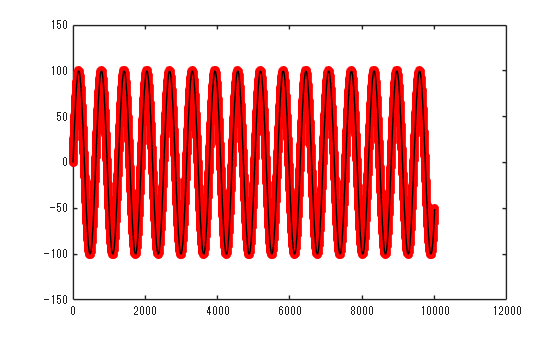

clear; close all
steps=10000;
a=1.9999; b=1;
u(1)=0; u(2)=1; for n=3:steps+1; u(n)=u(n-1)*a-u(n-2)*b; end
y=100*sin(0:0.01:steps*0.01);
plot(u, 'ro'); hold on; plot(y, 'k'); hold off

以下が実行されると，次の図ができます．

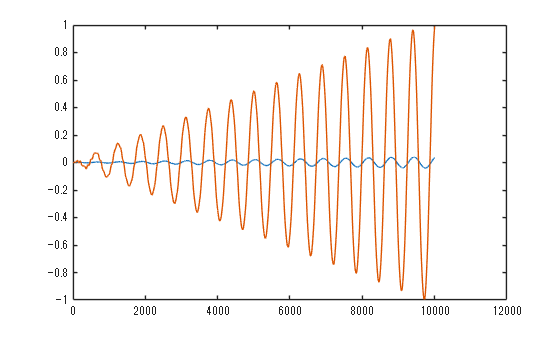

figure

% ルンゲ-クッタ法(ode45) （大学専門課程の学生さん向けのオプションです）
% y'' = -y を1階の連立方程式 y1'=y2, y2'=-y1 に変換して解く
[~, Y] = ode45(@(t,y) [y(2); -y(1)], 0:0.01:steps*0.01, [0; 100]);
y2 = Y(:,1)'; % 位置の解を抽出し、uと合わせるために行ベクトルに転置

plot(u-y); hold on; plot(y2-y)

この図において，青線は，上の図の｢数列のマジック｣（数値近似解u）と理論厳密解yの差です．青線は，振幅100のサイン曲線の振幅が100であることを考慮すると小さいことがわかります．しかし，計算ステップが増えるにつれ，差が大きくなっています．このまま一方的に増大するのでしょうか？

#### *4次ルンゲ・クッタ法の補足説明【***大学専門課程の学生の皆さん向け***】*

***大学専門課程の学生の皆さん****は，オレンジ色の線（4次のルンゲ-クッタ法；前進差分法と理論厳密解との差）にも注目してください．3.4.1節の条件の場合は，数列のマジックの方が精度が高いことが確認できます．*

*高校や大学の物理の数値近似解計算の導入教育では，前進差分である1次のルンゲ-クッタ法のオイラー法を教える場合が多いです．4次のルンゲ・クッタ法はオイラー法よりも精度が良いことで知られていて，大学の理工系学部では２年生以上で必ず習います．大学の理系学部では２年生の後期に習うのが典型的です．しかし，オイラー法でも｢数列のマジック｣よりも多くの説明が必要で，4次のルンゲ-クッタ法ではさらに多くの説明が必要なため，筆者の1年生4月の授業では，オイラー法も4次のルンゲ・クッタ法も触れていませんでした．今回GitHubへ公開すると，大学2年生以上の知識をお持ちの方もご覧頂けると想定し，ルンゲ・クッタ法との比較を加筆することにしました．*

### 3.4.2 $(a,b)=(1.99,1)$，$\Delta t=0.1$，steps=10000の場合

次に，さきほどの3.4.1節と同じ繰り返し回数の演算で，より多く振動したときの誤差を観察するために，時間刻みを $\Delta t=0.1$ と粗くし， $(a,b)=(1.99, 1)$ とします．すると，黒の実線（理論厳密解$10\sin(t)$）は，黒く塗りつぶされそうになるほど密に振動して描かれます．

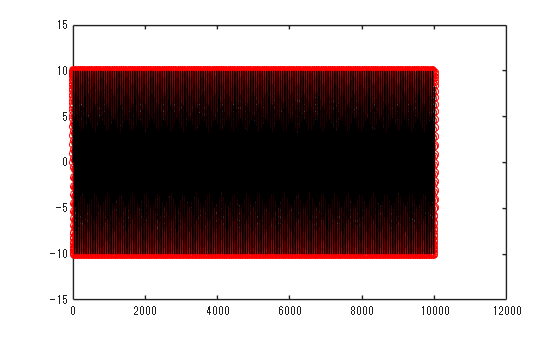

clear; close all
steps=10000;
u(1)=0; u(2)=1; for n=3:steps+1; u(n)=u(n-1)*1.99-u(n-2); end

y=10*sin(0:0.1:steps*0.1);

% 4次のルンゲ・クッタ法(ode45) （大学専門課程の学生さん向けのオプションです）
% y'' = -y を1階の連立方程式 y1'=y2, y2'=-y1 に変換して解く
[~, Y] = ode45(@(t,y) [y(2); -y(1)], 0:0.1:steps*0.1, [0; 10]);
y2 = Y(:,1)'; % 位置の解を抽出し、uと合わせるために行ベクトルに転置

plot(u, 'ro'); hold on; plot(y, 'k');

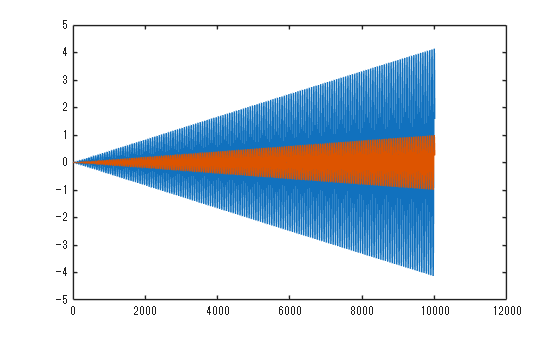

% Color=[221 84 0]/255; plot(y2,'Color',Color)
figure
plot(u-y)
hold on; plot(y2-y)

このとき，理論厳密解（黒線）と｢数列のマジック（赤丸）｣との差（青線）は増大し続け，サイン曲線の振幅10に対してかなり迫っています．両者の差は，さらに増大するのでしょうか？

#### *4次ルンゲ・クッタ法の補足説明【****大学専門課程の学生の皆さん向け****】*

*この3.4.2節の条件で，4次のルンゲ-クッタ法との比較をした場合は，4次のルンゲ・クッタ法（オレンジ色の線）の方が高精度に見えます．しかし，理論厳密解との差は，どちらも増大し続けています．数値近似解と理論厳密解の差は，さらに増大するのでしょうか？*

### 3.4.3 前節3.4.2と同一アルゴリズムのPythonコード

#### *4次ルンゲ・クッタ法の補足説明【****大学専門課程の学生の皆さん向け****】*

*上のPythonコードは，MATLABと同様に，4次のルンゲ-クッタ法も組み込まれています．*

## 3.5 位相誤差の蓄積とうなり現象

 MATLABコードもPythonコードも省略しますが，上に示したコードの中の計算ステップ数 steps を300,000（30万回）に変えて実行すると，下図の様に，離散化に起因する微小な位相誤差（周期，あるいは，振動数のわずかなズレ）が時間とともに累積し，「うなり（Beating）」現象の特徴が，マクロに見え始めます．20という「うなり（Beating）」の最大振幅は，理論厳密解$10\sin(t)$の振幅の2倍であることも重要です．これらから，｢数列のマジック｣（中心差分）の数値近似解と理論厳密解の周期（振動数）がわずかに異なるが，｢数列のマジック｣（中心差分）数値近似解の振幅が計算ステップ数が増加しても減っていないことがわかります．

MATLABやPythonなどの計算機言語では，表計算ソフト（Excel等）で困難であった多数回のループ演算を容易にコーディングできるため，数値近似解が内包する限界（離散化モデルの限界）を実感できます．

*【****大学専門課程の学生の皆さん向け****】学部や大学によってカリキュラムが異なりますが，なぜそうなるか，また，どれだけ異なるかは，主に大学1年生の基礎数学（微分積分，線形代数）から2年生の専門科目（常微分方程式，複素関数論など）にかけて，微分方程式の解の特性方程式や複素関数のオイラーの公式を学べば，理解できるようになります．詳細は，本リポジトリの専門課程で習うことを使った説明 [6]を参照して下さい．たとえば，この係数変化による数列の劇的な振る舞いの変化は，大学専門課程における特性方程式の「極とゼロ (Poles and Zeros)」の概念そのものを視覚化しています．また，｢数列のマジック｣的数値配列の演算が実際にどう使われているか[7]を併せてご参照いただき，大学での講義の導入としてご活用ください．*

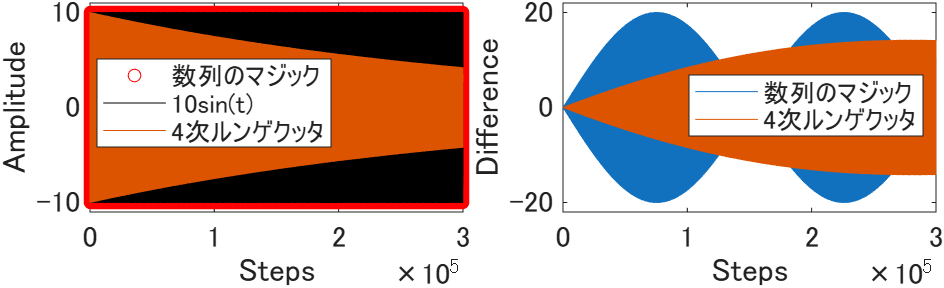

## 3.6 空間差分（波動方程式）への拡張

### 3.6.1 1次元の波動伝播

　時間軸における2階差分（隣接2項の和から中央の2倍を引く演算）の考え方は，空間軸の多次元（2階偏微分項：ラプラシアン）へとスムーズに拡張可能です ．右辺に空間の2階差分を組み込むことで，以下のようにMATLAB上で容易に1次元波動の伝播アニメーションをシミュレーションし，連続体力学や波動論の挙動を直感的に観察できます ．

単振動の計算コード

　｢直後＋直前－現在の2倍 = - 現在の小さな値倍｣

の右辺を

　｢直後＋直前－現在の2倍 = 左隣＋右隣－中央の2倍｣

の様に書き換えれば，運動方程式（微分方程式）を $\frac{d^2U}{dt^2} = -U$ を $\frac{d^2U}{dt^2} = \frac{d^2U}{dx^2}$ に書き換えることになります．端の質点の変位を0に固定すると，固定端反射の数値実験ができます．プログラムコーディングでは，端の質点の変位の初期値に0を与え，端の質点を時間発展の計算から除外すればＯＫです．

#### MATLABコードの例

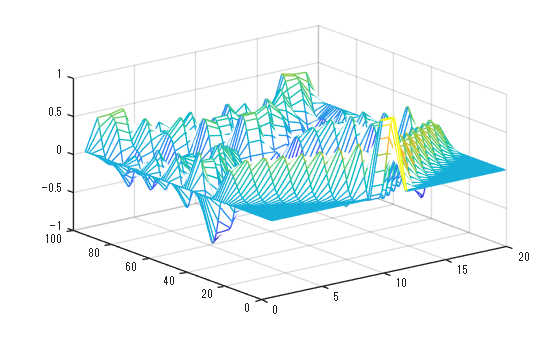

figure
U=zeros(100,20); % 100回の時間発展を，20個の質点に対して計算する領域確保
U(1,10:11)=1; U(2,10:11)=1; % 最初と次の時間ステップの，質点10と11の変位を1とする
% PythonのColab環境などでは｢U[0, 9:11] = 1｣，｢U[1, 9:11] = 1｣と書きます．Pythonだとここが大きく違います．以下の数値配列の範囲指定においても同様です．

for n=3:100 % Pythonの｢for n in range(2, 100):｣に対応します．

    %次の１行で（質点1+質点3, 質点2+質点4, ..., 質点18＋質点20）が一度に計算される
    f=U(n-1, 1:18)+U(n-1,3:20); % 左右隣接項の和
    %次の１行で，両隣の和から中央の2倍を引いた結果（ラプラシアンの原型）が得られる
    f=f-2*U(n-1, 2:19); 
    % 質点1と質点20は，0に固定するため計算しない．
    U(n, 2:19)=2*U(n-1, 2:19)-U(n-2, 2:19)+0.1*f; % 波動方程式の離散化
    mesh(U); drawnow

end % for n=3:100 % Pythonにはendが不要ですが，MATLABには要ります．

画面手前から右に向かい，質点1から質点20の変位量が高さで示され，画像の左側が時間進行方向です．MATLAB 2022a以降であれば，このライブスクリプトを実行し，スライドバーで色々な時刻の様子を詳しく観察できます．見る視点を少し変え，図のアニメーションを動画（MP4やAVI）として保存・エクスポートできるボタンもあります．次の4秒間のYoutube動画 [https://youtu.be/08CE5n18Tqk](https://youtu.be/08CE5n18Tqk) はそうして得たものです．

#### 【注意】MATLAB アニメーションのツール

2026年7月現在，上の1次元アニメーションと下の2次元アニメーションの実行完了後に，この1次元アニメーションのスライドバーを操作すると，上のFigureウィンドウに1次元波動伝播ではなく2次元の波が描画されてしまう問題を確認しています．この問題を回避するコードを追加するとプログラムが複雑になるため，本教材では意図的に追加を見送っています．もし，1次元波動伝播のアニメーションをスライドバーで操作・観察したい場合は，後述する2次元アニメーションのコードをコメントアウト（または削除）してから実行してください．

#### Pythonコードの例

MATLABの `drawnow` を用いたアニメーション機能は非常に直感的ですが，Pythonにおいても「Google Colab（Jupyter Notebook）」環境を活用することで，コードを肥大化させることなくMATLABと同等のシンプルさでアニメーション（パラパラ漫画風の描画）を実装できます．

以下は，2026年7月の時点で，上のMATLABコードをGoogle Geminiに与え，生成してもらったPythonコードです．Pythonコードの方が長く見えますが，波動の時間発展の計算をする核心部分は，MATLABと同様にコンパクトです．以下のPythonコードは，ユーザーがスマートフォンやPCのブラウザからGoogle Colab上で実行し，波の伝播と反射を，波打つひものような動きで観察するためのものです．

画面に表示したい場合は以下をPythonコードの一番下に加筆します．

plt.show()

### 3.6.2 2次元の波動伝播

　上のコードにおける，1次元の隣接２点の平均をラプラシアンと扱う部分を，２次元的な４つの隣接点の平均をラプラシアンとするように変更し，初期値を中央だけに与え，漸化式の計算を反復すると，２次元的な波の伝播の様子も観察できます．固定端反射の数値実験になるように端の質点の扱いは，1次元の場合と同様にします．次のMATLABコードを実行し，視点を少し変えると，[https://youtu.be/NThFZbwJDh0](https://youtu.be/NThFZbwJDh0) で紹介した動画を簡単に作成できます．

#### MATLABコードの例

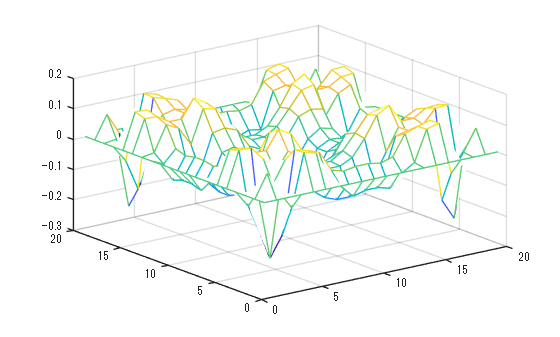

% 2次元の波動伝播を観察するためのMATLAB scriptの例．
% MATLAB Live Editorを使うと簡単にアニメーション動画を作れます．
figure
U_n = zeros(20,20); U_n_1=U_n; % 現在と直後の保存領域を0にする．
U_n_1(10:11,10:11) = ones(2,2); U_n_2 = U_n_1; % 中央4点のみ直前と現在の変位1．
for n=1:120
    sum4 = U_n_1(1:18,2:19) + U_n_1(3:20,2:19); % 一つの水平方向の隣接点の和
    sum4 = sum4 + U_n_1(2:19,1:18) + U_n_1(2:19,3:20); % 直交する方向の隣接点の和
    laplacian = U_n_1(2:19,2:19) - sum4/4; % Laplacian的なもの
    % 現在の2倍－直前－Laplacian*伝搬速度*時間刻み
    U_n(2:19,2:19) = 2*U_n_1(2:19,2:19) - U_n_2(2:19,2:19) - 0.1*laplacian;
    mesh(U_n);drawnow
    U_n_2 = U_n_1; U_n_1 = U_n; % データの保存場所の移動（現在→直前；直後→現在）
end % iterate from "for n=1:100" to this "end"

#### Pythonコードの例

以下には，MATLABコードと，2026年7月に生成AIによってMATLABコードから生成したPythonコードの例を示します．滑らかなアニメーション表示をするように，生成AIに指示したため，上のPythonコードより長くなっていますが，生成AIの自動生成でも，ここまでできるようになっていました．

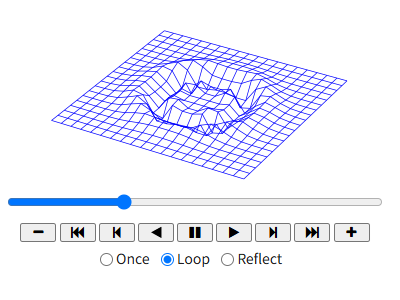

以下はPythonのコード例です．Google Colab上で実行すると，上の様な表示になり，詳しく観察できます．

--- 補足：GIFファイルとして保存したい場合は以下を，Pythonコードの最後に書き足して実行して下さい ---

anim.save('wave_2d.gif', writer='pillow', fps=20)

print("GIFファイルを保存しました．")

## 3.7 ライセンス

プログラムコードおよび文書資料は，[クリエイティブ コモンズ 表示 4.0 国際 (CC BY 4.0)]([https://creativecommons.org/licenses/by/4.0/deed.ja](https://creativecommons.org/licenses/by/4.0/deed.ja)) ライセンスの下で提供されています．

## 3.8 引用情報（CITATION）

本 GitHub リポジトリのプログラムや解説データを引用される場合は，以下のZenodoが発行する永続DOIを参照してください． [DOIの挿入予定位置(Zenodoにて仮発行されたDOIを記載)]

## 参考文献および注（References and Notes）

[1]: 立命館大学シラバス 理工学部物理科学科「ミクロとマクロの世界」(2016) ※Microsoft Excel を使用していた時代．[https://syllabus.ritsumei.ac.jp/syllabus/s/r-syllabus/a0ifD000003F2pUQAS/201631211?language=ja](https://syllabus.ritsumei.ac.jp/syllabus/s/r-syllabus/a0ifD000003F2pUQAS/201631211?language=ja) (2026年7月閲覧) 

[2]: 同上 (2018) [https://syllabus.ritsumei.ac.jp/syllabus/s/r-syllabus/a0ifD000003Ee1qQAC/201831549?language=ja](https://syllabus.ritsumei.ac.jp/syllabus/s/r-syllabus/a0ifD000003Ee1qQAC/201831549?language=ja)) (2026年7月閲覧) ※MATLAB が使えるようになった最初の年度のシラバス．情報処理教室は依然として必要であった．

[3]: 同上 (2023) [https://syllabus.ritsumei.ac.jp/syllabus/s/r-syllabus/a0ifD000003EblHQAS/202331861?language=ja](https://syllabus.ritsumei.ac.jp/syllabus/s/r-syllabus/a0ifD000003EblHQAS/202331861?language=ja) (2026年7月閲覧) ※コロナ・パンデミック後，全受講生がPCを持つようになり，情報処理教室が不要になった．

[4]: 先行研究および公的教材の例: R. V. Jones, Am. J. Phys. 63 (1995) 978. / 鈴木亨, 鈴木久男, 物理教育 44 (1996) 381. / 文部科学省『高等学校情報科「情報Ⅰ」教員研修用教材（第3章 専門的な課題解決とプログラミング）』(2019) pp. 118-123.

[5]: 本リポジトリのREADME.md

[6]: 本リポジトリの 5_Magic_of_Sequence_Advanced.md(｢数列のマジック｣の大学2～3年生向け種明かし）

[7]: 本リポジトリの 6_Magic_of_Sequence_Edu_Significance.md (｢数列のマジック｣が大学で習う何を先取りしているか)

[8]: 本リポジトリの 7_Historical_Context_via_AI.md (筆者が生成AIから学んだ｢数列のマジック｣の歴史的背景)

[9]: MATLABの最新バージョンの基本機能は，パソコンのウェブ・ブラウザ上で使える MATLAB Onlineがあります．ウェブで"MATLAB Online"を検索し，ヒットしたところから使い始めることができます．正規ライセンスを持っていなくても，毎月20時間以内であれば無料で利用可能です．Mathworks社のアカウントを作成する必要はありますが，無料のコースや他の教育資源も利用できます．

[10]: スマホのブラウザでも｢数列のマジック｣を楽しめるHTMLアプリ．本リポジトリの index.html 